%Interface01 para o método de Euler
%
%CHAMADA DE FUNÇÕES:
% » NEuler
% » dsolve
%Alunos:
%   10/04/2021 - Francisco Ruivo .: a2021142024@isec.pt
%   10/04/2021 - Daniel Rodrigues .: a2021142013@isec.pt

clc
clear

disp('----- Método de Euler para EDO ------ ');

----- Método de Euler para EDO ------ 


disp(' ');

 
% sExata = dsolve('Dy=y+exp(3*t)')
% sExataP = dsolve('Dy=y+exp(3*t)', 'y(1)=2')

strF='y+exp(3*t)';
f=@(t,y) eval(vectorize(strF));

a  = 1;
b  = 1.5;
n  = 2;
y0 = 2;

yEuler=NEuler(f,a,b,n,y0);

sExata=dsolve(['Dy=', strF],...
                ['y(',num2str(a),')=',num2str(y0)]);

g=@(t) eval(vectorize(char(sExata)));
h=(b-a)/n;
t=a:h:b;
yExata=g(t);

erroEuler=abs(yExata-yEuler);
tabela=[t.', yEuler.', yExata.', erroEuler.'];
disp('----- Solução do PVI em modo tabela de valores ----')

----- Solução do PVI em modo tabela de valores ----


disp(tabela)

    1.0000    2.0000    2.0000         0
    1.2500    7.5214   10.9334    3.4120
    1.5000   20.0320   31.7483   11.7163




input('Prima numa tecla para continuar')
disp('----- Solução do PVI em modo gráfico ----')

----- Solução do PVI em modo gráfico ----


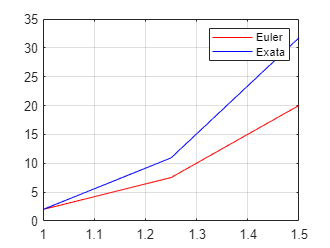

plot(t,yEuler,'-r')
hold on
plot(t,yExata, 'b')
hold off
grid on
legend('Euler','Exata')

shg;